**Exercise 1-6. **This exercise will test the concept of condition number. We will test the accuracy of solving Ax = b when noise is added to b for matrices A with different condition numbers. 

(a) To build the two matrices, generate a random U ∈ R100×100 and V ∈ R100×100 and then create two Σ matrices: the first Σ will have singular values spaced logarithmically from 100 to 1, and the second Σ will have singular values spaced logarithmically from 100 to 10^−6. Use these matrices to create two A matrices, one with a condition number of 100 and the other with a condition number of 100 million. Now create a random b vector, solve for x using the two methods, and compare the results. Add a small ε to b, with norm 10^−6 smaller than the norm of b. Now solve for x using this new b + ε and compare the results. 						

% Define matrix dimensions
n = 100;

% Generate random matrices U and V
U = randn(n);
V = ?

% Perform QR factorization to get orthogonal matrices
[U, ~] = qr(U);
[V, ~] = ?

% Create Σ matrices with logarithmic spacing
sigma1 = logspace(log10(100), log10(1), n);         % Singular values for condition number 100
sigma2 = ?      % Singular values for condition number 1e8

% Create diagonal Σ matrices
Sigma1 = diag(sigma1);
Sigma2 = ?

% Construct matrices A1 and A2
A1 = U * Sigma1 * V';   % Matrix with condition number 100
A2 = ?   % Matrix with condition number 1e8

% Create a random b vector
b = randn(n, 1);

% Solve Ax = b for both A1 and A2
x1 = ?
x2 = ?

% Add a small epsilon to b (epsilon norm is 1e-6 smaller than norm(b))
epsilon = 1e-6 * norm(b) * randn(n, 1);
b_epsilon = b + epsilon;

% Solve for x using b + epsilon
x1_epsilon = ?
x2_epsilon = ?

% Compare the solutions before and after adding epsilon
error1 = norm(x1 - x1_epsilon) / norm(x1);
error2 = ?

% Display results
fprintf('Condition number of A1 (approximately 100):\n');

Condition number of A1 (approximately 100):


fprintf(['Error in solution after perturbing b: %.3e\n'], error1);

Error in solution after perturbing b: 9.757e-06


fprintf('\n');

fprintf('Condition number of A2 (approximately 1e8):\n');

Condition number of A2 (approximately 1e8):


fprintf('Error in solution after perturbing b: %.3e\n', error2);

Error in solution after perturbing b: 9.513e-06


b)  Now repeat the experiment above with many different noise vectors ε and compute the distribution of the error; plot this error as a histogram and explain the shape. 	

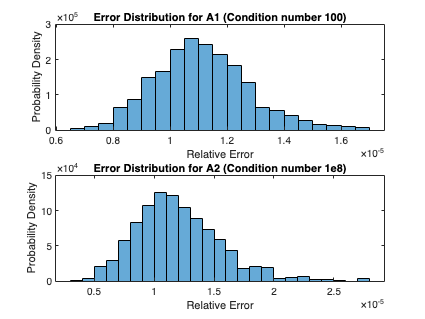

% Define matrix dimensions
n = 100;
num_trials = 1000;  % Number of trials for different noise vectors

...

% Initialize arrays to store the errors
errors1 = zeros(num_trials, 1);
errors2 = ?

% Loop through multiple trials to compute error distribution
for i = 1:num_trials
    % Generate a small epsilon (norm is 1e-6 smaller than norm(b))
    epsilon = ?
    b_epsilon = ?
    
    % Solve for x using b + epsilon
    x1_epsilon = ?
    x2_epsilon = ?
    
    % Compute relative error for each condition number
    errors1(i) = ?
    errors2(i) = ?
end

% Plot histograms of the error distributions
figure;
subplot(2,1,1);
histogram(errors1, 'Normalization', 'pdf');
title('Error Distribution for A1 (Condition number 100)');
xlabel('Relative Error');
ylabel('Probability Density');

subplot(2,1,2);
histogram(errors2, 'Normalization', 'pdf');
title('Error Distribution for A2 (Condition number 1e8)');
xlabel('Relative Error');
ylabel('Probability Density');

(c)  Repeat the above experiment comparing two A matrices with different singular value distributions: the first Σ will have values spaced linearly from 100 to 1 and the second Σ will have value spaced logarithmically from 100 to 1. Does anything change? Please explain why yes or no. 

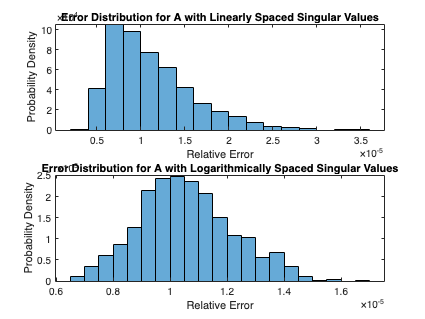

% Define matrix dimensions
n = 100;
num_trials = 1000;  % Number of trials for different noise vectors

...

% Loop through multiple trials to compute error distribution
for i = 1:num_trials
    ...
end

% Plot histograms of the error distributions
figure;
subplot(2,1,1);
histogram(errors_linear, 'Normalization', 'pdf');
title('Error Distribution for A with Linearly Spaced Singular Values');
xlabel('Relative Error');
ylabel('Probability Density');

subplot(2,1,2);
histogram(errors_log, 'Normalization', 'pdf');
title('Error Distribution for A with Logarithmically Spaced Singular Values');
xlabel('Relative Error');
ylabel('Probability Density');

(d)  Repeat the above experiment, but now with an A matrix that has size 100 × 10. Explain any changes.

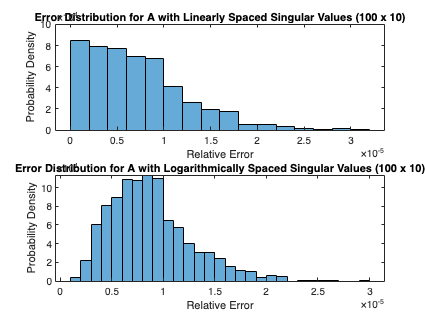

% Define matrix dimensions
m = 100; % Number of rows
n = 10;  % Number of columns
num_trials = 1000;  % Number of trials for different noise vectors

% Generate random matrices U and V
U = randn(m, m);  % U is now m x m

...

% Loop through multiple trials to compute error distribution
for i = 1:num_trials
    ...
end

% Plot histograms of the error distributions
figure;
subplot(2,1,1);
histogram(errors_linear, 'Normalization', 'pdf');
title('Error Distribution for A with Linearly Spaced Singular Values (100 x 10)');
xlabel('Relative Error');
ylabel('Probability Density');

subplot(2,1,2);
histogram(errors_log, 'Normalization', 'pdf');
title('Error Distribution for A with Logarithmically Spaced Singular Values (100 x 10)');
xlabel('Relative Error');
ylabel('Probability Density');